# **Fuselage Structural Layout**

The script is for the structural layout of the fuselage and to determine the frame and stringer shapes sizes and placements to achieve the least mass and to staisfy the maximum stress requirements 

## Housekeeping and importing relevant variables

clear
clc 
close all

load Mohkap_workspace.mat

## Discretising the fuselage for the rib and stringer spacing

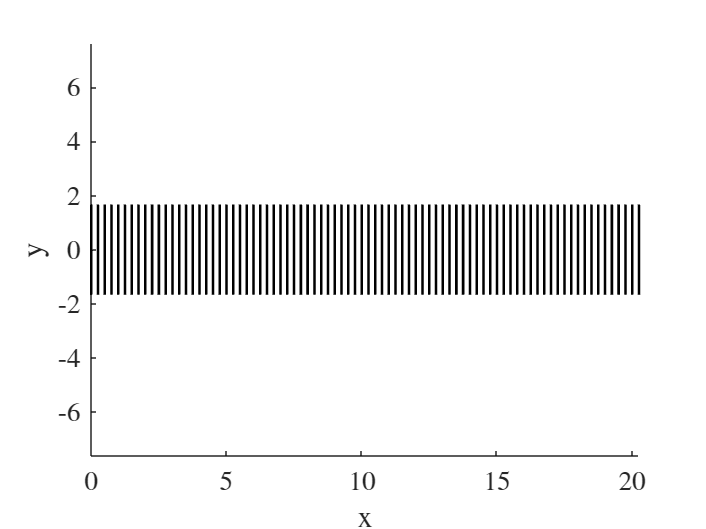

Fuselage.frame_spacing = 0.25; %m
Fuselage.stringer_spacing = 10; %degrees starting from the top anticlockwise

cabin_length = 20.48;
frames = 0:Fuselage.frame_spacing:cabin_length;
Fuselage.all_frames = frames;
stringers = 0:Fuselage.stringer_spacing:180;
Fuselage.cabin_radius = de_fuselage/2;

frame_diameters = ones(1, length(frames)).*Fuselage.cabin_radius.*2;

stringer_z = Fuselage.cabin_radius.*cosd(stringers);
stringer_y = -Fuselage.cabin_radius.*sind(stringers);

stringer_z = [stringer_z, -stringer_z(2:end-1)];
stringer_y = [stringer_y, -stringer_y(2:end-1)];

Fuselage.frame = struct;
Fuselage.stringer = struct;

Fuselage.stringer(1, length(stringer_y)).y = 0;
Fuselage.stringer(1, length(stringer_z)).z = 0;
Fuselage.frame(1, length(frames)).x = 0;
Fuselage.stringer(1).angle = 0;

for i=1:length(stringer_z) 
    Fuselage.stringer(i).y = stringer_y(i);
    Fuselage.stringer(i).z = stringer_z(i);
    Fuselage.stringer(i).angle = 0 + Fuselage.stringer_spacing.*(i-1);
end

for i=1:length(frames)
    Fuselage.frame(i).x = frames(i);
    Fuselage.frame(i).diameter = frame_diameters(i);
end

% Plotting the fueslage layout from the end of the nose to the end of the
% cabin - which forms the cylindrical part of the layout

% Start by plotting the frames at the appropriate location 
figure(1)
for i=1:length(frames)
    [y, z] = circle(0, 0, Fuselage.cabin_radius);
    hold on
    x = ones(1, length(y)).*frames(i);
    plot3(x, y, z, "k", "LineWidth", 1.5)
    axis equal
end

xlabel("x", "Interpreter","latex", "FontSize", 16)
ylabel("y", "Interpreter","latex", "FontSize", 16)
zlabel("z", "Interpreter","latex", "FontSize", 16)

set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")
hold off
axis equal

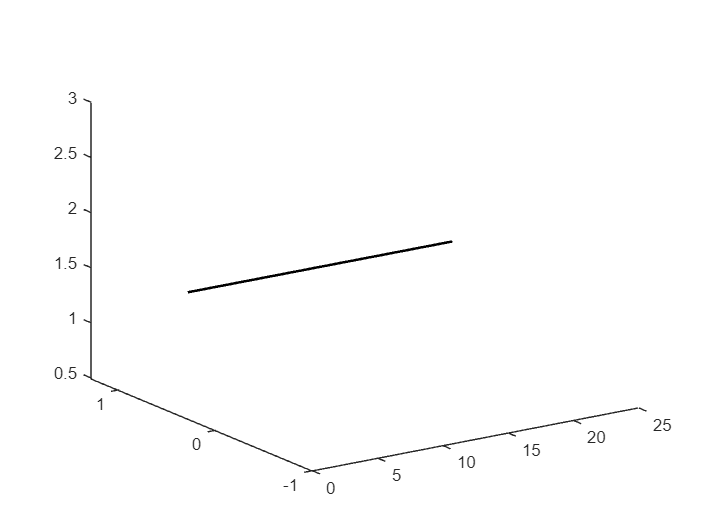

% Plot the stringers that run along the whole of the fuselage 
for j=1:length(stringer_y)
    plot3([frames(1) frames(end)], Fuselage.stringer(j).y .*[1 1], Fuselage.stringer(j).z .*[1 1], "k", "LineWidth", 1.5)
end

view([-34.1 22.1])

## Define the material and material properties of the skin, stringers and frames


Fuselage.stringer_material = "Aluminium 2024 T861";
Fuselage.frame_material = "Aluminium 7075 T76511";
Fuselage.skin_material = "Aluminium 2024 T36";

Fuselage.stringer_yield_stress = 431e6;
Fuselage.frame_yield_stress = 650e6;
Fuselage.skin_yield_stress = 378e6;

Fuselage.stringer_ultimate_stress = 468.5e6;
Fuselage.frame_ultimate_stress = 679e6;
Fuselage.skin_ultimate_stress = 501e6;

Fuselage.stringer_shear_stress = 187e6;
Fuselage.frame_shear_stress = 187e6;
Fuselage.skin_shear_stress = 320e6;

Fuselage.stringer_density = 2765;
Fuselage.frame_density = 2850;
Fuselage.skin_density = 2765;

Fuselage.stringer_E = 73.85e9;
Fuselage.frame_E = 73.5e9;
Fuselage.skin_E = 73.85e9;

## Determine the shear flow of on each of the frames due to bending (due to shear force at each point along the fuselage)

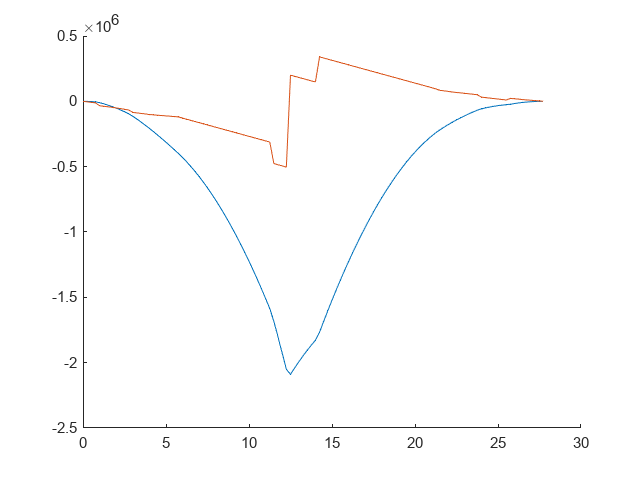

CONVERGED!!!


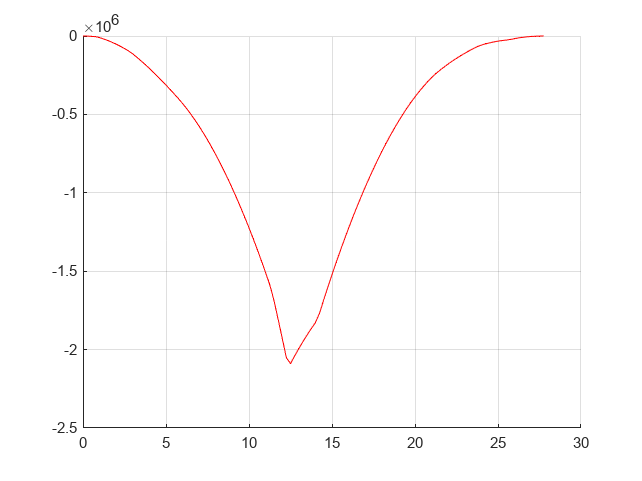


% Find qb first by making a cut at panel between 1 and 2 and calculate
% shear flow positive anticlockwise

[SF_fuselage, BM_fuselage,disc,L] = Testing_inertial_Loads(1, 3.75, Fuselage.frame_spacing);

    "Did not converge in,"    "1000"    "iterations"



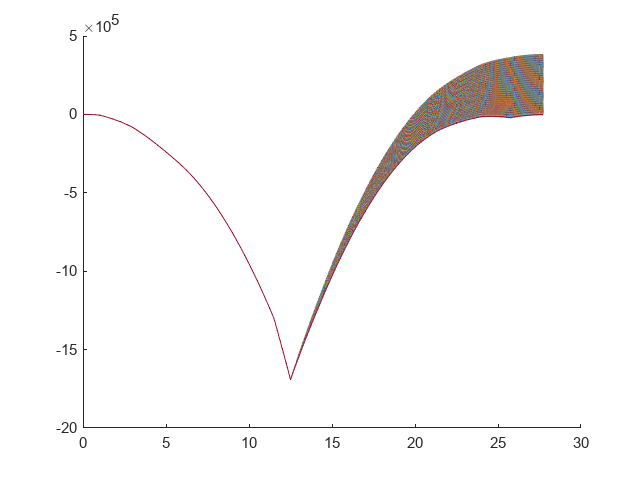

CONVERGED!!!


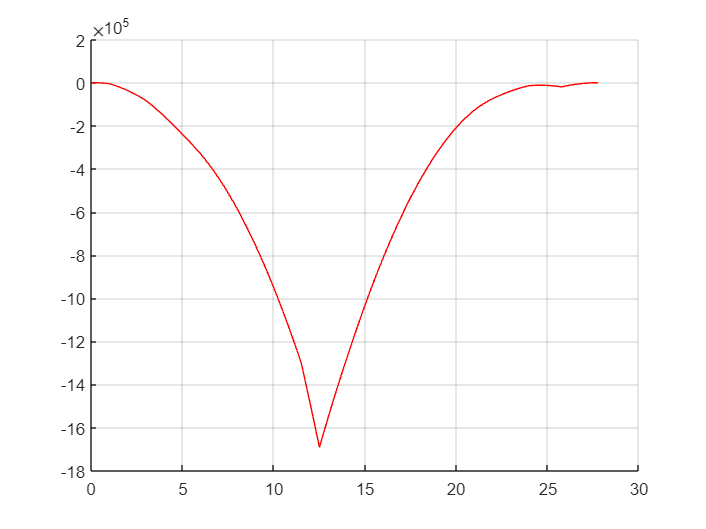

[SF_fuselage_landing, BM_fuselage_landing,disc_landing,L_landing] = Testing_inertial_Loads(2, 3, Fuselage.frame_spacing);


figure()
p1 = plot(disc(1, :), SF_fuselage, "-k", "LineWidth", 2, "DisplayName", "Loading at $V_A$ and $V_D$");
hold on
p2 = plot(disc_landing(1,:), SF_fuselage_landing, "-r", "LineWidth", 2, "DisplayName", "Landing nose off");

xlabel("Fuselage station from nose (m)", "Interpreter","latex", "FontSize", 16)
ylabel("Shear force (N)", "Interpreter","latex", "FontSize", 16)


plot([-100 100], [0 0], "-k", "LineWidth", 0.5)
legend([p1 p2], "Interpreter","latex", "FontSize", 16)

grid on 
grid minor

xlim([0 30])

set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")

hold off

figure()
p1 = plot(disc(1, :), BM_fuselage, "-k", "LineWidth", 2, "DisplayName", "Loading at $V_A$ and $V_D$");
hold on
p2 = plot(disc_landing(1,:), BM_fuselage_landing, "-r", "LineWidth", 2, "DisplayName", "Landing nose off");

xlabel("Fuselage station from nose (m)", "Interpreter","latex", "FontSize", 16)
ylabel("Bending Moment (Nm)", "Interpreter","latex", "FontSize", 16)

plot([-100 100], [0 0], "-k", "LineWidth", 0.5)

legend([p1 p2], "Interpreter","latex", "FontSize", 16)

grid on 
grid minor

xlim([0 30])

set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")

hold off



clf
cabin_start = round(4.0183/Fuselage.frame_spacing)*Fuselage.frame_spacing;
cabin_end = round((20.488+4.0183)/Fuselage.frame_spacing)*Fuselage.frame_spacing;

SF_fuselage = SF_fuselage(find(disc(1, :) == cabin_start):find(disc(1,:) == cabin_end));
BM_fuselage = BM_fuselage(find(disc(1, :) == cabin_start):find(disc(1,:) == cabin_end));



# ***Design of the Skin-Stringer panels***

## Iterate through different stringer spacings to get different skin thicknesses

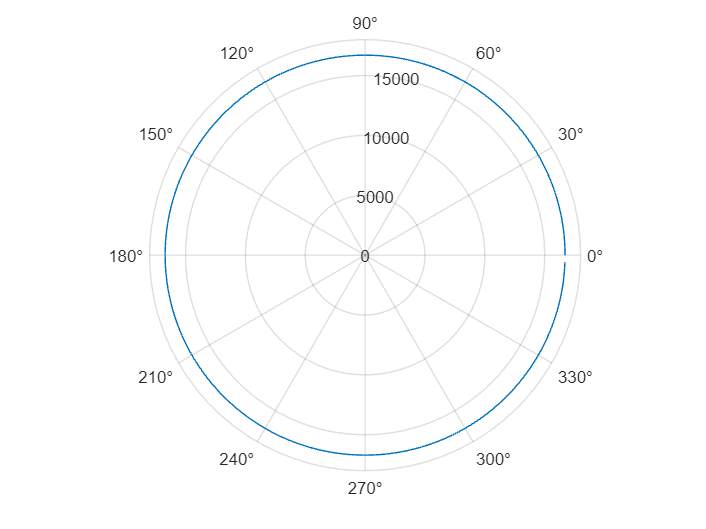


stringer_spacings = [2]; % degrees

thicknesses = [];

for stringer_spacing = stringer_spacings

    Fuselage.stringer_spacing = stringer_spacing; %degrees starting from the top anticlockwise
    
    stringers = 0:Fuselage.stringer_spacing:180;
    
    stringer_z = Fuselage.cabin_radius.*cosd(stringers);
    stringer_y = -Fuselage.cabin_radius.*sind(stringers);
    
    stringer_z = [stringer_z, -stringer_z(2:end-1)];
    stringer_y = [stringer_y, -stringer_y(2:end-1)];
    
    Fuselage.stringer = struct;
    
    Fuselage.stringer(1, length(stringer_y)).y = 0;
    Fuselage.stringer(1, length(stringer_z)).z = 0;
    Fuselage.stringer(1).angle = 0;

    Fuselage.Booms.q  = [];
    Fuselage.Booms.q(1:length(frames),1:length(stringer_y)) = 0;
    
    for i=1:length(stringer_z) 
        Fuselage.stringer(i).y = stringer_y(i);
        Fuselage.stringer(i).z = stringer_z(i);
        Fuselage.stringer(i).angle = 0 + Fuselage.stringer_spacing.*(i-1);
    end
    
    Fuselage.Booms.q(1:length(frames),1:length(stringer_y)) = 0;
    
    for i = 1:length(frames)
        for j=1:length(stringer_y)
            Fuselage.Booms.q(i, j) = -(SF_fuselage(i)/(pi*Fuselage.frame(i).diameter/2)).* sind(Fuselage.stringer(j).angle)- (28685 * (2.2426+1.67))/(2*pi*(Fuselage.frame(i).diameter/2)^2); 
        end
    end
    
    figure(7)
    polarplot([Fuselage.stringer(1:end).angle].*pi/180, [Fuselage.Booms.q(42, 1:end)], "-o")

    polarplot([Fuselage.stringer(1:end).angle].*pi/180, Fuselage.frame(42).diameter/2 .* ones(1, length(stringer_y)) .* 10000)
    hold off
    % Find the max shear flow for each of the frames 
    
    Fuselage.frame(1).max_q = 0;
    
    for i = 1:length(frames)
        Fuselage.frame(i).max_q = max(abs([Fuselage.Booms.q(i, 1:end)]));
    end
    
    max_q = max([Fuselage.frame(1:end).max_q]);

    Fuselage.skin.thickness_shear_stress = max([Fuselage.frame(1:end).max_q])./Fuselage.skin_shear_stress;

    thicknesses = [thicknesses Fuselage.skin.thickness_shear_stress];
end

## Boom shear panel idealisation of each fuselage section

% The goal of the process is to determine the optimum dimensions of the
% stringers such that the mass of the whole fuselage is the least that it
% can be and the max stress in the stringers is equal to the maximum stress
% allowed in the structure.

stringer_Areas = [findArea(0.0023, 0.0126, 0.0038)]; %m^2
stringer_spacings = [360/134]; % degrees


figure(3)
figure(4)
idx = 0;

## Determining the Rc and Rs constraints for the buckling of the skin due to shear and bending

    2.6866



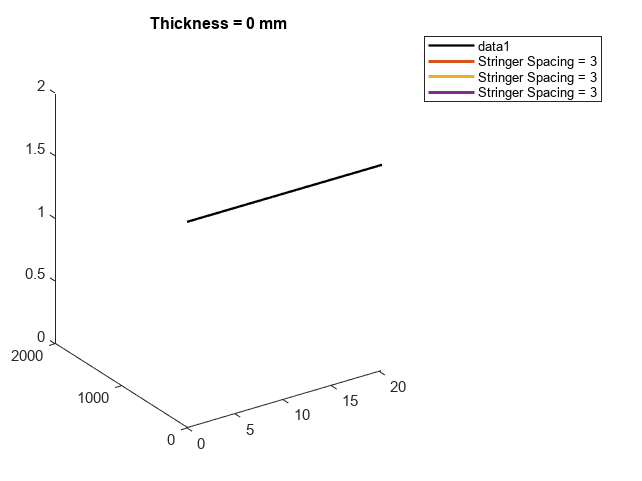

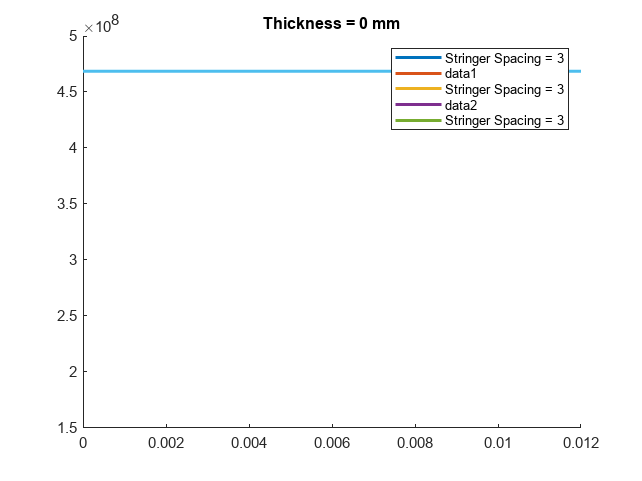

% Determine the sigma_c,crit and sigma_s,crit
% Determine the sigma_c and sigma_s
% Check if Rc + Rs^2 <= 0.99 condition is satisfied 

Kc = 3.62; % Compressive stress buckling coefficient
Ks = 5; % Shear stress buckling coefficient 


% Both K values selected for all edges simply supported for conservative
% design 

thicknesses_buckling = 1.7e-3; %[0.5:0.1:4].*10^(-3);

Fuselage.thickness = struct;
Fuselage.thickness(1,length(thicknesses_buckling)).RcRs = [];

for t_idx = 1:length(thicknesses_buckling)
    Fuselage.skin.thickness = thicknesses_buckling(t_idx);

    Fuselage.sigma_c_crit = zeros(1,length(stringer_spacings));
    Fuselage.sigma_s_crit = zeros(1,length(stringer_spacings));
    Fuselage.max_stress = zeros(length(stringer_spacings), length(stringer_Areas));
    Fuselage.max_shear_stress = zeros(length(stringer_spacings), length(stringer_Areas));

    Fuselage.skin.panel_length = Fuselage.cabin_radius .* deg2rad(stringer_spacings);
    Fuselage.stringer_spacing  = stringer_spacings;

    Fuselage.skin.panel_bending_eff_length = Fuselage.skin.panel_length + 15*Fuselage.skin.thickness;
    Fuselage.skin.panel_buckling_eff_length = Fuselage.skin.panel_length - 15*Fuselage.skin.thickness;

    Fuselage.sigma_c_crit = Kc * Fuselage.skin_E * (Fuselage.skin.thickness./Fuselage.skin.panel_buckling_eff_length).^2;
    Fuselage.sigma_s_crit = Ks * Fuselage.skin_E * (Fuselage.skin.thickness./Fuselage.skin.panel_buckling_eff_length).^2;

    idx = 0;

    for stringer_spacing = stringer_spacings
        idx = idx + 1;
        masses = [];
        areas = [];
        num_stringers = [];
        max_stresses = [];

        disp(stringer_spacing)

        for stringer_Area = stringer_Areas

            Fuselage.stringer = struct;

            stringers = 0:Fuselage.stringer_spacing(idx):180;

            stringer_z = Fuselage.cabin_radius.*cosd(stringers);
            stringer_y = -Fuselage.cabin_radius.*sind(stringers);

            stringer_z = [stringer_z, -stringer_z(2:end-1)];
            stringer_y = [stringer_y, -stringer_y(2:end-1)];

            Fuselage.stringer(1, length(stringer_y)).y = 0;
            Fuselage.stringer(1, length(stringer_z)).z = 0;
            Fuselage.stringer(1).angle = 0;

            for i=1:length(stringer_z)
                Fuselage.stringer(i).y = stringer_y(i);
                Fuselage.stringer(i).z = stringer_z(i);
                Fuselage.stringer(i).angle = 0 + Fuselage.stringer_spacing(idx).*(i-1);
            end


            for i=1:length(stringer_z)
                Fuselage.stringer(i).Area = stringer_Area;
            end

            Fuselage.mass = 0;

            Fuselage.Boom = struct;
            Fuselage.Boom(1, length(stringer_y)).Area = 0;


            Fuselage.Boom(1).Area = Fuselage.stringer(1).Area + 15*Fuselage.skin.thickness^2; %Fuselage.Boom(1).Area = Fuselage.stringer(1).Area + (Fuselage.skin.panel_bending_eff_length.*Fuselage.skin.thickness/6).*(2 + Fuselage.stringer(2).z/Fuselage.stringer(1).z) * 2;

            for i=2:length(stringer_y)-1
                Fuselage.Boom(i).Area = Fuselage.stringer(i).Area + 15*Fuselage.skin.thickness^2;

                %             if (Fuselage.stringer(i).z ~= 0)
                %                 Fuselage.Boom(i).Area = Fuselage.stringer(i).Area + (Fuselage.skin.panel_bending_eff_length.*Fuselage.skin.thickness/6).*(2 + Fuselage.stringer(i+1).z/Fuselage.stringer(i).z + 2 + Fuselage.stringer(i-1).z/Fuselage.stringer(i).z);
                %             else
                %                 Fuselage.Boom(i).Area = Fuselage.stringer(i).Area + 0;
                %             end

            end

            %Fuselage.Boom(length(stringer_y)/4 + 1).Area = Fuselage.stringer(length(stringer_y)/4 + 1).Area + 0;
            %Fuselage.Boom(3*length(stringer_y)/4 + 1).Area = Fuselage.stringer(length(stringer_y)/4 + 1).Area + 0;

            Fuselage.Boom(length(stringer_y)).Area = Fuselage.stringer(length(stringer_y)).Area + 15*Fuselage.skin.thickness^2; %Fuselage.stringer(end).Area + (Fuselage.skin.panel_length.*Fuselage.skin.thickness/6).*(2 + Fuselage.stringer(end-1).z/Fuselage.stringer(end).z + 2 + Fuselage.stringer(1).z/Fuselage.stringer(end).z);

            Fuselage.Iyy = 2*Fuselage.stringer(1).z .^2 .* Fuselage.Boom(1).Area;

            for i = 2:length(stringer_y)/4
                Fuselage.Iyy = Fuselage.Iyy + 4*Fuselage.stringer(i).z .^2 .* Fuselage.Boom(i).Area;
            end
            %Determining the bending stresses due to the bending moments on the fuselage
            Fuselage.Booms.sigma_x = [];
            Fuselage.Booms.sigma_x(1, 1) = 0;

            for i = 1:length(frames)
                for j=1:length(stringer_y)

                    Fuselage.Booms.sigma_x(i, j) = BM_fuselage(i).*Fuselage.stringer(j).z ./ Fuselage.Iyy;

                end
            end

            Fuselage.mass = sum([Fuselage.Boom(1:end).Area]) * Fuselage.stringer_density * cabin_length + Fuselage.skin.thickness * 2*Fuselage.cabin_radius*pi * cabin_length * Fuselage.skin_density;

            areas = [areas Fuselage.Boom(1).Area];
            masses = [masses Fuselage.mass];
            max_stresses = [max_stresses max(Fuselage.Booms.sigma_x(:))];
            num_stringers = [num_stringers length(stringer_z)];

        end

        Fuselage.max_stress(idx, :) = max_stresses;
        Fuselage.max_shear_stress(idx, :) = max([Fuselage.frame(1:end).max_q])./Fuselage.skin.thickness;

        % Plot the max stress for each area against the area of the stringer
        %plot(areas, max_stresses/Fuselage.stringer_ultimate_stress, "LineWidth", 2);
        figure(3)
        hold on
        plot(areas, masses, "LineWidth", 2, "DisplayName", "Stringer Spacing = " + int2str(stringer_spacing))
        legend()
        title("Thickness = " + int2str(thicknesses_buckling(t_idx)) + " mm")

        figure(4)
        hold on
        plot(areas, max_stresses, "LineWidth", 2, "DisplayName", "Stringer Spacing = " + int2str(stringer_spacing))
        legend
        title("Thickness = " + int2str(thicknesses_buckling(t_idx)) + " mm")
        hold off
        pause(1)

    end

    figure(4)
    hold on
    plot([0 1000], [Fuselage.stringer_ultimate_stress Fuselage.stringer_ultimate_stress], "LineWidth", 2)
    hold off

    xlim([0 0.012])

    %Determine If the Rc, Rs condition is met for each stringer spacing 

    % Rc + Rs^2 <= 0.99
    % sigma_c/sigma_c_crit + (sigma_s/sigma_s_crit)^2 <= 0.99

    for i = 1:length(stringer_Areas)

        Fuselage.thickness(t_idx).RcRs(:, i) = (Fuselage.max_stress(:, i)./Fuselage.sigma_c_crit' + (Fuselage.max_shear_stress(:, 1)./Fuselage.sigma_s_crit').^2 <= 0.99);
    end
end

## Applying the FARRAR efficiency factor

% Right now these values are for t = 1.7mm, stringer spacing of 4 degs - 90
% stringers and stringer area of 9e-4 m^2.
As_over_bt = stringer_Areas(4)./(Fuselage.skin.thickness*Fuselage.skin.panel_length(3))

ts_over_t = 0.97;
F = 0.85;

Fuselage.stringer_dims.thickness = 0.97*Fuselage.skin.thickness

% Z stringers


## Determining skin thicknesses due to the pressure loads


pressure_8000ft = 75262.38;
pressure_40000ft = 18753.93;

pressure_diff = pressure_8000ft - pressure_40000ft

pressure_diff = 5.6508e+04

t_hoop = FuselageDiameter * pressure_diff/(2*Fuselage.skin_yield_stress)

t_hoop = 2.2424e-04

t_longitudinal = FuselageDiameter * pressure_diff/(4*Fuselage.skin_yield_stress)

t_longitudinal = 1.1212e-04

## Plot the stress distribution at the frame with the max stress

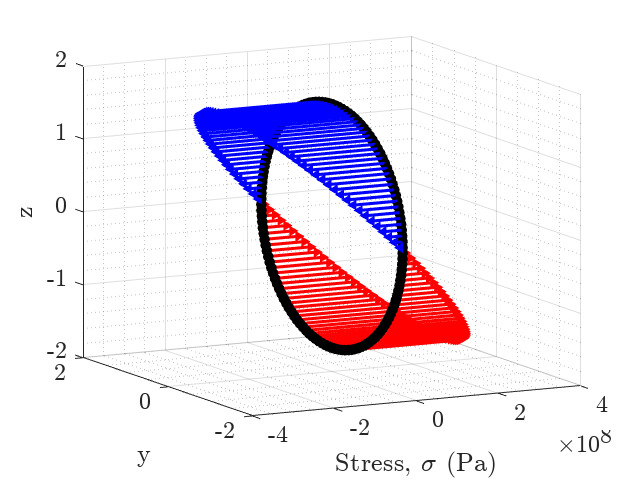

% First plot the frame and the booms

figure()
max_stress_each_frame = max(Fuselage.Booms.sigma_x, [], 2);
frame_index = find(abs(max_stress_each_frame) == max(abs(max_stress_each_frame)));
[y_frame, z_frame] = circle(0, 0, Fuselage.cabin_radius);
plot3(zeros(1, length(y_frame)), y_frame, z_frame, "k", "LineWidth", 2)

for i = 1:length(stringer_y)
    hold on
    plot3(0, Fuselage.stringer(i).y, Fuselage.stringer(i).z, "o", "LineWidth",2, "MarkerSize", 5, "MarkerFaceColor","k", "MarkerEdgeColor", "k")
    if(Fuselage.Booms.sigma_x(frame_index, i) >= 0)
        plot3([0, Fuselage.Booms.sigma_x(frame_index, i)], [Fuselage.stringer(i).y, Fuselage.stringer(i).y], [Fuselage.stringer(i).z, Fuselage.stringer(i).z], "-r", "LineWidth",2)
        plot3(Fuselage.Booms.sigma_x(frame_index, i), Fuselage.stringer(i).y, Fuselage.stringer(i).z, "->r", "LineWidth",2, "MarkerSize", 3, "MarkerFaceColor","r", "MarkerEdgeColor", "r")
    elseif(Fuselage.Booms.sigma_x(frame_index, i) < 0)
        plot3([0, Fuselage.Booms.sigma_x(frame_index, i)], [Fuselage.stringer(i).y, Fuselage.stringer(i).y], [Fuselage.stringer(i).z, Fuselage.stringer(i).z], "-b", "LineWidth",2)
        plot3(Fuselage.Booms.sigma_x(frame_index, i), Fuselage.stringer(i).y, Fuselage.stringer(i).z, "-<b", "LineWidth",2, "MarkerSize", 3, "MarkerFaceColor","b", "MarkerEdgeColor", "b")

    end

end
xlabel("Stress, $\sigma$ (Pa)", "Interpreter","latex", "FontSize", 16)
ylabel("y", "Interpreter","latex", "FontSize", 16)
zlabel("z", "Interpreter","latex", "FontSize", 16)

set(gca, "FontSize", 16, "TickLabelInterpreter", "latex")


ylim([-2.00 2.00])
zlim([-2.00 2.00])
view([-27.25 12.66])
grid on 
grid minor

# ***Design of the light frames placed along the whole fuselage***

% The optimisation problem means that we have to find the I required for
% each frame first 

% minimise mass for given (tf, hf, bf) such that I(tf, hf, bf) = I required
C_f = 1/16000;

Nf_s = 0.5;

Min_Area_Values = zeros(length(Nf_s), 5);

for i = 1:length(Nf_s)
    Fuselage.frames.If_required = (C_f * max(abs(BM_fuselage)) * (2*Fuselage.cabin_radius)^2)/(Fuselage.frame_E * Nf_s(i));
    I_required = Fuselage.frames.If_required;

    %I_required = @(Lf)(C_f * max(abs(BM_fuselage)) * (2*Fuselage.cabin_radius)^2)/(Fuselage.frame_E * Lf);
    
    h_t = 0.0277;
    %sigma_a = Fuselage.max_stress;
    %As = findArea(0.0023, 0.0126, 0.0038);
    %Is = findI_stringer(0.0023, 0.0126, 0.0038); 
    
    % Setting up the optimisation problem 
    Area = @(tf, hf, bf) hf.*tf + 2*(bf.*tf);
    Mass = @(tf, hf, bf) Area(tf, hf, bf) * 2*pi*Fuselage.cabin_radius * Fuselage.frame_density*(cabin_length./Lf);
    find_tf = @(hf, bf, Lf) I_required(Lf)./(hf.^3/12 + 2*bf.*(hf./2).^2);
    obj = @(tf, hf, bf) Area(teq(tf, hf, bf), hf, bf);
    % Defining the non linear I constraint 
    
    c = @(x)[] ;%sigma_a - Fuselage.stringer_E*Is*pi^2/(x(4)^2 * As);
    ceq = @(x)((x(2)^3 * x(1))/12 + 2*((x(3)*x(1)^3)/12) + 2*(x(3)*x(1)*(x(2)/2 - x(1)/2)^2)) - I_required;
    
    Iconstraint = @(x)deal(c(x), ceq(x));
    
    tf_min = 0.001; % 1mm minimum thickness
    tf_max = 0.1; % 10cm max thickness
    
    hf_min = 1.5*h_t;
    hf_max = 0.15;
    
    bf_min = 0.01;
    bf_max = 0.15;

    Lf_min = 25e-2;
    Lf_max = 75e-2;
    
    X0 = [5,10, 10].*(10^-2);
    
    options = optimoptions('fmincon','Display','iter');
    [minArea_dims, fval] = fmincon(@(x) Area(x(1), x(2), x(3)), X0, [], [], [], [], [tf_min, hf_min, bf_min], [tf_max, hf_max, bf_max], Iconstraint, options)

    Min_Area_Values(i, :) = [Nf_s(i), minArea_dims, fval];
end

Unrecognized function or variable 'BM_fuselage'.

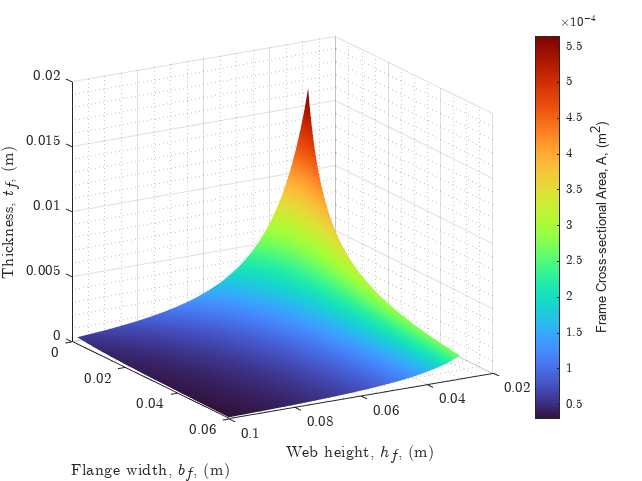


Fuselage.frames.tf = minArea_dims(1);
Fuselage.frames.hf = minArea_dims(2);
Fuselage.frames.bf = minArea_dims(3);

Fuselage.frames.mass = Area(Fuselage.frames.tf, Fuselage.frames.hf, Fuselage.frames.bf) * 2*pi*Fuselage.cabin_radius * Fuselage.frame_density;

% Plot the surface for the area with respect to the three variables - tf,
% hf, bf

hf_s = linspace(hf_min, 0.1, 1000);
bf_s = linspace(bf_min, 0.06, 1000);

[H_f, B_f] = meshgrid(hf_s, bf_s);

T_f = find_tf(H_f, B_f, 0.5);

Areas = Area(T_f, H_f, B_f);
figure(7)
sc = surf(H_f, B_f, T_f, Areas, "EdgeColor","none");
hold on
%plot3(Fuselage.frames.hf, Fuselage.frames.hf, Fuselage.frames.hf, "o", "MarkerSize", 5, "MarkerEdgeColor", "r", "MarkerFaceColor", "r")
hold off

xlabel("Web height, $h_f$, (m)", "Interpreter","latex", "FontSize", 12)
ylabel("Flange width, $b_f$, (m)", "Interpreter","latex", "FontSize", 12)
zlabel("Thickness, $t_f$, (m)", "Interpreter","latex", "FontSize", 12)
set(gca, "FontSize", 10, "TickLabelInterpreter", "latex")

grid minor
colormap turbo
c = colorbar('TickLabelInterpreter', 'latex');
c.Label.String = "Frame Cross-sectional Area, A, (m^2)";
view([149.228 19.059])

## Optimsation of the fuselage structure to minimise mass while still meeting all the bending and buckling constraints

% To optimise the fuselage, we need a scalar function that only returns the
% mass of the fusealge, given the parameters which we are optimising (Ns,
% ts, hs, bs) which will be our objective function. The optimisation will
% implicitly run the optimsation of the light frames for each set of
% paramenters, however the value of the upper bound of the light frame may
% change depending on what hs the function has picked.


Ns_min = 10;
ts_min = 0.001;
hs_min = 0.001;
t_skin_min = thicknesses(1);

Ns_max = 360;
ts_max = 0.15;
hs_max = 0.15;
t_skin_max = 0.15;

flange_web_ratio = 0.3;

X_s_0 = [0.002, 0.02, 0.002, 118];
N = 90

N = 90


Fuselage.frame_spacing = 0.5;

options = optimoptions('fmincon','Display','iter','ConstraintTolerance',1e-20,'OptimalityTolerance',1e-20,'UseParallel',false);
[min_mass_values, min_mass] = fmincon(@(x) fus_min_mass(x(1), x(2), x(3), x(4), Fuselage, BM_fuselage, SF_fuselage, cabin_length, flange_web_ratio), X_s_0, [], [], [], [], [ts_min, hs_min, t_skin_min, Ns_min], [ts_max, hs_max, t_skin_max, Ns_max], [], options)


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

min_mass_values =     0.0019    0.0176    0.0018  118.0000


min_mass = 1.6819e+03

## Grid Search and plotting surfaces to show the different regions of the fuselage parameters

stringer_t = linspace(0.001, 0.01, 10);
stringer_h = linspace(0.01, 0.10, 10);
skin_t = linspace(0.001, 0.01, 10);

stringer_number = 10:10:200;

masses = [];

for str_num = 1:length(stringer_number)
    stringer_number(str_num)
    for str_t = 1:length(stringer_t)
        for str_h = 1:length(stringer_h)
            for skn_t = 1:length(skin_t)
                    

                Fuselage.stringers.ts = stringer_t(str_t);
                Fuselage.stringers.hs = stringer_h(str_h);
                Fuselage.stringers.bs = flange_web_ratio * stringer_h(str_h);

                Fuselage.skin.thickness = skin_t(skn_t);

                Fuselage.ts_over_tskin = stringer_t(str_t)/skin_t(skn_t);

                Fuselage.stringers.flange_web_ratio = flange_web_ratio;

                % Make sure the number of stringers is an integer
                Ns = round(stringer_number(str_num));
                Fuselage.stringers.Ns = Ns;

                [Fuselage] = FuselageStructuralLayout(Fuselage, BM_fuselage, SF_fuselage);

                Fuselage.skin_stringer_mass = Fuselage.skin.thickness*2*pi*Fuselage.cabin_radius*cabin_length*Fuselage.skin_density + Fuselage.stringers.Ns*Fuselage.stringers.As*cabin_length*Fuselage.stringer_density;
                Fuselage.frames.mass = findArea(Fuselage.frames.tf, Fuselage.frames.hf, Fuselage.frames.bf) * 2*pi*Fuselage.cabin_radius * Fuselage.frame_density * floor((cabin_length./Fuselage.frame_spacing));

                fuselageMass = Fuselage.skin_stringer_mass + Fuselage.frames.mass;

                Fuselage.mass = fuselageMass*Fuselage.error_weight;

                masses(str_num, str_t, str_h, skn_t) = fuselageMass*Fuselage.error_weight;
            end
        end
    end
end


## Ploting surfaces for number of stringers and the other three variabels with two held constant

% Constant web height and constant sringer thickness

%stringer_t = linspace(0.001, 0.01, 10);
stringer_h = linspace(0.0105, 0.06, 500);
%skin_t = linspace(0.001, 0.01, 100);

stringer_number = 100:1:140;

[SN, HS] = meshgrid(stringer_number, stringer_h);

masses_SN_HS = [];

for i = 1:length(stringer_number)
    stringer_number(i)
     for j = 1:length(stringer_h)

        Fuselage.stringers.ts = 1.4e-3;
        Fuselage.stringers.hs = stringer_h(j);
        Fuselage.stringers.bs = flange_web_ratio * stringer_h(j);

        Fuselage.skin.thickness = 1.7e-3;

        Fuselage.ts_over_tskin = 1.3e-3/0.0017;

        Fuselage.stringers.flange_web_ratio = flange_web_ratio;

        % Make sure the number of stringers is an integer
        Ns = round(stringer_number(i));
        Fuselage.stringers.Ns = Ns;

        [Fuselage] = FuselageStructuralLayout(Fuselage, BM_fuselage, SF_fuselage);

        Fuselage.skin_stringer_mass = Fuselage.skin.thickness*2*pi*Fuselage.cabin_radius*cabin_length*Fuselage.skin_density + Fuselage.stringers.Ns*Fuselage.stringers.As*cabin_length*Fuselage.stringer_density;
        Fuselage.frames.mass = findArea(Fuselage.frames.tf, Fuselage.frames.hf, Fuselage.frames.bf) * 2*pi*Fuselage.cabin_radius * Fuselage.frame_density * floor((cabin_length./Fuselage.frame_spacing));

        fuselageMass = Fuselage.skin_stringer_mass + Fuselage.frames.mass;

        Fuselage.mass = fuselageMass*Fuselage.error_weight;

        masses_SN_HS(i,j) = fuselageMass;


    end
end

ans = 100


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 101


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 102


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 103


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 104


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 105


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 106


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 107


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 108


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 109


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 110


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 111


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 112


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 113


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 114


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 115


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 116


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 117


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 118


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 119


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 120


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 121


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 122


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 123


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 124


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 125


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 126


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 127


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 128


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 129


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 130


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 131


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 132


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 133


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 134


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 135


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 136


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 137


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 138


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 139


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 

ans = 140


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum possible. Constraints satisfied.

fmincon stopped because the 


figure()
surfc(HS, SN, (masses_SN_HS'), "EdgeColor","none")
hold on
contourf(HS, SN, (masses_SN_HS'))
colormap("turbo")

colorbar

xlabel("Stringer height, $h_s$ , (m)", "Interpreter", "latex", "FontSize", 12)
ylabel("Number of stringers, $N_s$", "Interpreter", "latex", "FontSize", 12)
zlabel("Mass (kg)", "Interpreter", "latex", "FontSize", 12)

set(gca, "FontSize", 12, "TickLabelInterpreter", "latex")

c = colorbar('TickLabelInterpreter', 'latex');
c.Label.String = "Fuselage Mass (kg)";



view([158 33])

shading(gca,'interp')

## Global Search and Multistart


% The results above are highly dependant on the initial condition and it
% seems as if there is a local minima for each value of NS that is
% initialised. Hence the problem is highly non-convex.

% To get a global minimum we need to use either the multistart of global
% search algorithms in MATLAB

% Try Global Search to find the global minima.

X_s_0 = [0.002, 0.01, 0.002];
Ns = [114];

MinValues = zeros(length(Ns), 6);
options = optimoptions('fmincon','Display','iter','ConstraintTolerance',1e-20,'OptimalityTolerance',1e-20,'UseParallel',false);

for i = 1:length(Ns)
    globalSearchProblem = createOptimProblem('fmincon', ...
        'objective', @(x) fus_min_mass(x(1), x(2), x(3), Ns(i), Fuselage, BM_fuselage, SF_fuselage, cabin_length, flange_web_ratio), ...
        "x0", X_s_0, "lb", [ts_min, hs_min, t_skin_min], ....
        "ub", [ts_max, hs_max, t_skin_max], "options", ...
        options);
    
    %disp("Validating problem setup...")
    %[global_min_mass_values, global_min_mass] = fmincon(globalSearchProblem)
    
    gs = GlobalSearch("Display", "iter", "PlotFcn","gsplotbestf");
    
    rng(14, "twister")
    disp("Running global search...")
    [global_min_mass_values, global_min_mass] = run(gs, globalSearchProblem)

    MinValues(i, :) = [Ns(i), global_min_mass_values(1), global_min_mass_values(2), global_min_mass_values(3), global_min_mass_values(2)*flange_web_ratio, global_min_mass]
end

Running global search...



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Local minimum found that satisfies the constraints.

Optimization completed because the objective fu

## Functions to help with the optimisation

% function [c, ceq] = Iconstraint(x)
%     c =[];
%     ceq(1) = ((x(2)^3 * x(1))/12 + 2*((x(3)*x(1)^3)/12) + 2*(x(3)*x(1)*(x(2)/2 - x(1)/2)^2)) - 8.376960492790974e-08; % the last number is the I required. Needs to be changed whenever the parameters are changed.
% end


function fuselageMass = fus_min_mass(ts, hs, t_skin, Ns, Fuselage, BM_fuselage, SF_fuselage, cabin_length, flange_web_ratio)

    Fuselage.stringers.ts = ts;
    Fuselage.stringers.hs = hs;
    Fuselage.stringers.bs = flange_web_ratio * hs;

    Fuselage.skin.thickness = t_skin;

    Fuselage.ts_over_tskin = ts/t_skin;

    Fuselage.stringers.flange_web_ratio = flange_web_ratio;
    
    % Make sure the number of stringers is an integer
    Ns = round(Ns);
    Fuselage.stringers.Ns = Ns;
    
    [Fuselage] = FuselageStructuralLayout(Fuselage, BM_fuselage, SF_fuselage);

    Fuselage.skin_stringer_mass = Fuselage.skin.thickness*2*pi*Fuselage.cabin_radius*cabin_length*Fuselage.skin_density + Fuselage.stringers.Ns*Fuselage.stringers.As*cabin_length*Fuselage.stringer_density;
    Fuselage.frames.mass = findArea(Fuselage.frames.tf, Fuselage.frames.hf, Fuselage.frames.bf) * 2*pi*Fuselage.cabin_radius * Fuselage.frame_density * floor((cabin_length./Fuselage.frame_spacing));

    fuselageMass = Fuselage.skin_stringer_mass + Fuselage.frames.mass;
    fuselageMass  = fuselageMass * Fuselage.error_weight;

    Fuselage.mass = fuselageMass;

end

function [Fuselage] = FuselageStructuralLayout(Fuselage, BM_fuselage, SF_fuselage)
    
  
    Fuselage.stringers.spacing = 360./Fuselage.stringers.Ns;
    
    
    % Initialise the variables in the fuselage structure to make sure there
    % are no clashes
    Fuselage = InitialiseFuselage(Fuselage);

    % Find the boom areas
    Fuselage = FindBoomAreas(Fuselage);

    % Find the Iyy for each frame
    Fuselage = FindI(Fuselage);
    
    % Find the maximum bending stress 
    [sigma_c, Fuselage] = GetMaxCompStress(Fuselage, BM_fuselage);
    
    % Find the maximum compressive stress
    [sigma_s, Fuselage] = GetMaxShearStress(Fuselage, SF_fuselage);

    % Find the critical buckling stresses due to shear and compression
    Kc = 3.62;
    Ks = 5;
    [sigma_c_crit, sigma_s_crit, Fuselage] = GetCriticalStresses(Fuselage, Kc, Ks);
    
    error_weight = 1;

    % Check if tensile yield/ultimate strength is reached or exceeded and
    % if so set the error weight to 1e+10
    [tensileYield] = CheckTensileYield(sigma_c, Fuselage.stringer_yield_stress);

    if tensileYield == true
        error_weight = 1e10;
    end

    % Check if shear yield is reached or exceeded and
    % if so set the error weight to 1e+10
    [shearYield] = CheckShearYield(sigma_s, Fuselage.skin_shear_stress);

    if shearYield == true
        error_weight = 1e10;
    end
    
    % Check if the Rc+Rs^2 <= 0.99 condition for combined buckling is
    % satisfied and if not then set the error weight to 
    [RcRs] = CheckRcRsCondition(sigma_c, sigma_s, sigma_c_crit, sigma_s_crit);

    if RcRs == false
        error_weight = 1e10;
    end
    
    % Check if the values of As/bt and ts/t are in the raange of he farrar
    % efficiency required
    [farraar_range, As] = CheckFarrarEfficiency(Fuselage.stringers.ts, Fuselage.stringers.hs, Fuselage.stringers.bs, Fuselage.skin.thickness, Fuselage.skin.panel_buckling_eff_length, Fuselage.ts_over_tskin);

    if farraar_range == false
        error_weight = 1e10;
    end

    Fuselage.stringers.As = As;
    
    % Check if the panel effective length is less than 0 aand if so set
    % error weight 1e10;

    if Fuselage.skin.panel_buckling_eff_length <= 0
        error_weight = 1e10;
    end

    % Now call the light frame optimisation function to determine the
    % dimensions of the frame cross section

    plotSurface = false;
    Fuselage = OptimiseLightFrames(Fuselage, BM_fuselage, plotSurface);
    Fuselage.error_weight = error_weight;


end

function [Fuselage] = FindBoomAreas(Fuselage)

    for i=1:length(Fuselage.stringer_z)
        Fuselage.stringer(i).Area = findArea(Fuselage.stringers.ts, Fuselage.stringers.hs, Fuselage.stringers.bs);
    end

    Fuselage.Boom = struct;

    Fuselage.Boom(1,length(Fuselage.stringer_y)).Area = 0;
    
    for i=1:length(Fuselage.stringer_y)
        Fuselage.Boom(i).Area = Fuselage.stringer(i).Area + 15*Fuselage.skin.thickness^2;
    end

end

function A = findArea(ts, hs, bs)
    A = 2*(bs*ts) + hs*ts;
end

function [Fuselage] = InitialiseFuselage(Fuselage)

    stringers = 0:Fuselage.stringers.spacing:180;
    
    Fuselage.stringer_z = [];
    Fuselage.stringer_y = [];

    Fuselage.stringer_z = Fuselage.cabin_radius.*cosd(stringers);
    Fuselage.stringer_y = -Fuselage.cabin_radius.*sind(stringers);
    
    Fuselage.stringer_z = [Fuselage.stringer_z, -Fuselage.stringer_z(2:end-1)];
    Fuselage.stringer_y = [Fuselage.stringer_y, -Fuselage.stringer_y(2:end-1)];
    
    Fuselage.frame = struct;
    Fuselage.stringer = struct;
    
    Fuselage.stringer(1, length(Fuselage.stringer_y)).y = 0;
    Fuselage.stringer(1, length(Fuselage.stringer_z)).z = 0;
    Fuselage.stringer(1).angle = 0;
    
    for i=1:length(Fuselage.stringer_z)
        Fuselage.stringer(i).y = Fuselage.stringer_y(i);
        Fuselage.stringer(i).z = Fuselage.stringer_z(i);
        Fuselage.stringer(i).angle = 0 + Fuselage.stringers.spacing .*(i-1);
    end
    

    Fuselage.skin.panel_length = Fuselage.cabin_radius .* deg2rad(Fuselage.stringers.spacing);

    Fuselage.skin.panel_bending_eff_length = Fuselage.skin.panel_length + 15*Fuselage.skin.thickness;
    Fuselage.skin.panel_buckling_eff_length = Fuselage.skin.panel_length - 15*Fuselage.skin.thickness;

end

function Fuselage = FindI(Fuselage)
    Fuselage.Iyy = sum([Fuselage.Boom(1:end).Area].*[Fuselage.stringer(1:end).z].^2);
end


function [sigma_c, Fuselage] = GetMaxCompStress(Fuselage, BM_fuselage)

    Fuselage.Booms.sigma_x = [];
    Fuselage.Booms.sigma_x(1, 1) = 0;
    
    for i = 1:length(Fuselage.all_frames)
        for j=1:length(Fuselage.stringer_y)
    
            Fuselage.Booms.sigma_x(i, j) = BM_fuselage(i).*Fuselage.stringer(j).z ./ Fuselage.Iyy;
    
        end
    end

    Fuselage.max_stress = max(abs(Fuselage.Booms.sigma_x(:)));
    sigma_c = max(abs(Fuselage.Booms.sigma_x(:)));

end

function [sigma_s, Fuselage] = GetMaxShearStress(Fuselage, SF_fuselage)

    Fuselage.Booms.q = zeros(length(Fuselage.all_frames),length(Fuselage.stringer_y));

    for i = 1:length(Fuselage.all_frames)
        for j=1:length(Fuselage.stringer_y)
            Fuselage.Booms.q(i, j) = -(SF_fuselage(i)/(pi*Fuselage.cabin_radius)).*sind(Fuselage.stringer(j).angle);
        end
    end

    % Find the max shear flow for each of the frames 
    
    Fuselage.frame(1).max_q = 0;
    
    for i = 1:length(Fuselage.all_frames)
        Fuselage.frame(i).max_q = max(abs([Fuselage.Booms.q(i, 1:end)]));
    end
    
    
    Fuselage.skin.thickness_shear_stress = max([Fuselage.frame(1:end).max_q])./Fuselage.skin_shear_stress;

    sigma_s = max([Fuselage.frame(1:end).max_q])./Fuselage.stringers.ts;


end

function [sigma_c_crit, sigma_s_crit, Fuselage] = GetCriticalStresses(Fuselage, Kc, Ks)

    Fuselage.sigma_c_crit = 0;
    Fuselage.sigma_s_crit = 0;
    
    Fuselage.sigma_c_crit = Kc * Fuselage.skin_E * (Fuselage.skin.thickness./Fuselage.skin.panel_buckling_eff_length).^2;
    Fuselage.sigma_s_crit = Ks * Fuselage.skin_E * (Fuselage.skin.thickness./Fuselage.skin.panel_buckling_eff_length).^2;

    sigma_c_crit = Fuselage.sigma_c_crit;
    sigma_s_crit = Fuselage.sigma_s_crit;

end

function [tensileYield] = CheckTensileYield(sigma_c, sigma_yield)
    
    if sigma_c >= sigma_yield
        tensileYield = true;
    else
        tensileYield = false;
    end

end


function [shearYield] = CheckShearYield(sigma_s, sigma_shear)

    if sigma_s >= sigma_shear
        shearYield = true;
    else
        shearYield = false;
    end

end

function [RcRs] = CheckRcRsCondition(sigma_c, sigma_s, sigma_c_crit, sigma_s_crit)
    Rc_Rs_condition = sigma_c/sigma_c_crit + (sigma_s/sigma_s_crit)^2;
    
    if Rc_Rs_condition <= 0.99
        RcRs = true;
    else
        RcRs = false;
    end

end

function [farrar_range, As] = CheckFarrarEfficiency(ts, hs, bs, b, t, ts_over_t)
    As = findArea(ts, hs, bs);
    bt = b*t;

    if ((As/bt < 1.4 && As/bt > 0.4) && (ts_over_t > 0.5 && ts_over_t < 1.8))
        farrar_range = true;
    else
        farrar_range = false;
    end

end

function I_s = findI_stringer(ts, hs, bs)

I_s = (ts*hs^3)/12 + 2*(ts*bs * (hs/2)^2);

end

function [Fuselage] = OptimiseLightFrames(Fuselage, BM_fuselage, plotSurface)

    % The optimisation problem means that we have to find the I required for
    % each frame first
    
    % minimise mass for given (tf, hf, bf) such that I(tf, hf, bf) = I required
    C_f = 1/16000;
    Fuselage.frames.If_required = (C_f * max(abs(BM_fuselage)) * (2*Fuselage.cabin_radius)^2)/(Fuselage.frame_E * Fuselage.frame_spacing);
    I_required = Fuselage.frames.If_required;

    %sigma_a = Fuselage.max_stress;
    %As = findArea(Fuselage.stringers.ts, Fuselage.stringers.hs, Fuselage.stringers.bs);
    %Is = findI_stringer(Fuselage.stringers.ts, Fuselage.stringers.hs, Fuselage.stringers.bs); 
    
    
    % Setting up the optimisation problem
    Area = @(tf, hf, bf) hf.*tf + 2*(bf.*tf);
    find_tf = @(hf, bf) I_required./(hf.^3/12 + 2*bf.*(hf./2).^2);
    obj = @(tf, hf, bf) Area(teq(tf, hf, bf), hf, bf);

    c = @(x) [];%sigma_a - Fuselage.stringer_E*Is*pi^2/(x(4)^2 * As);
    ceq = @(x)((x(2)^3 * x(1))/12 + 2*((x(3)*x(1)^3)/12) + 2*(x(3)*x(1)*(x(2)/2 - x(1)/2)^2)) - I_required;

    Iconstraint = @(x)deal(c(x), ceq(x));

    
    tf_min = 0.001; % 1mm minimum thickness
    tf_max = 0.1; % 10cm max thickness
    
    hf_min = 1.5*Fuselage.stringers.hs;
    hf_max = 0.15;
    
    bf_min = 0.002;
    bf_max = 0.15;
    
    X0 = [1, 1, 1].*(10^-2);
    
    %options = optimoptions('fmincon','Display','iter');
    [minArea_dims] = fmincon(@(x) Area(x(1), x(2), x(3)), X0, [], [], [], [], [tf_min, hf_min, bf_min], [tf_max, hf_max, bf_max], Iconstraint);

    Fuselage.frames.tf = minArea_dims(1);
    Fuselage.frames.hf = minArea_dims(2);
    Fuselage.frames.bf = minArea_dims(3);

    if plotSurface
        figure()
        hf_s = linspace(hf_min, 0.06, 1000);
        bf_s = linspace(bf_min, 0.03, 1000);
        
        [H_f, B_f] = meshgrid(hf_s, bf_s);
        
        T_f = find_tf(H_f, B_f);
        
        Areas = Area(T_f, H_f, B_f);

        sc = surf(H_f, B_f, T_f, Areas, "EdgeColor","none");
        hold on
        %plot3(Fuselage.frames.hf, Fuselage.frames.hf, Fuselage.frames.hf, "o", "MarkerSize", 5, "MarkerEdgeColor", "r", "MarkerFaceColor", "r")
        hold off
        legend("Suface for constant I", "Frame dimensions at minima", "location", "north", "Interpreter","latex", "FontSize", 12)
        xlabel("Web height, $h_f$, (m)", "Interpreter","latex", "FontSize", 12)
        ylabel("Flange width, $b_f$, (m)", "Interpreter","latex", "FontSize", 12)
        zlabel("Thickness, $t_f$, (m)", "Interpreter","latex", "FontSize", 12)
        set(gca, "FontSize", 10, "TickLabelInterpreter", "latex")

        grid minor
        colormap jet
        c = colorbar('TickLabelInterpreter', 'latex');
        c.Label.String = "Frame Cross-sectional Area, A, (m^2)";
        view([149.228 19.059])

        legend("Position", [0.23234,0.87504,0.43013,0.10601])
    end

end